## Ejemplos

### 1. Crecimiento poblacional $P(t)$

% simbolica
syms P(t)
r = 1; b= 0.1; d = 0.001; P0 = 50;
eqn = diff(P) == r*P*(b-d*P);
cnd = P(0) == P0;

pP = dsolve(eqn, cnd)

$$pP = \frac{100}{{\mathrm{e}}^{-\frac{t}{10}}+1}$$

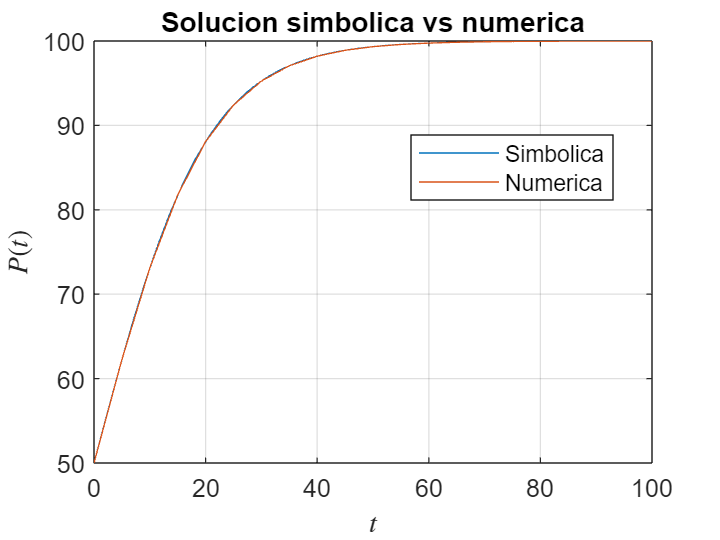

tspan = [0 100];
fplot(pP, tspan)
title('Solucion simbolica vs numerica')
xlabel('$t$', 'Interpreter','latex')
ylabel('$P(t)$', 'Interpreter','latex')
grid on
hold on

% numerica
f = @(t, p) p*(b-d*p);
[t, y] = odeRK4(f, P0, tspan, 5);
plot(t, y)
legend('Simbolica','Numerica', 'Location','best')
hold off

### 2. Cinetica quimica

% simbolica
syms c(t)
a0 = 4; b0 = 1;
k = 0.00713; c0 = 0;
tspan = [0 400];

eqn = diff(c) == k*((a0-c)^2)*(b0-c/2);
cnd = c(0) == c0;

pc = dsolve(eqn, cnd)

$$pc = 4-\frac{1}{\frac{W_{0}\left(-{\mathrm{e}}^{-\frac{713\,t}{50000}-\log\left(2\right)-\frac{1}{2}}\right)}{2}+\frac{1}{2}}$$

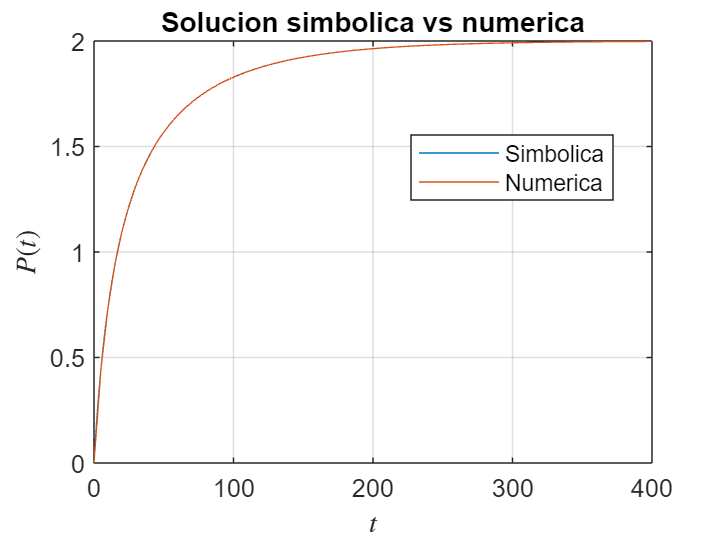

fplot(pc, tspan)
title('Solucion simbolica vs numerica')
xlabel('$t$', 'Interpreter','latex')
ylabel('$P(t)$', 'Interpreter','latex')
grid on
hold on

% numerica
f = @(t, c) k*((a0-c)^2)*(b0-c/2);
[t, y] = odeRK4(f, c0, tspan, 5);
plot(t, y)
legend('Simbolica','Numerica', 'Location','best')
hold off

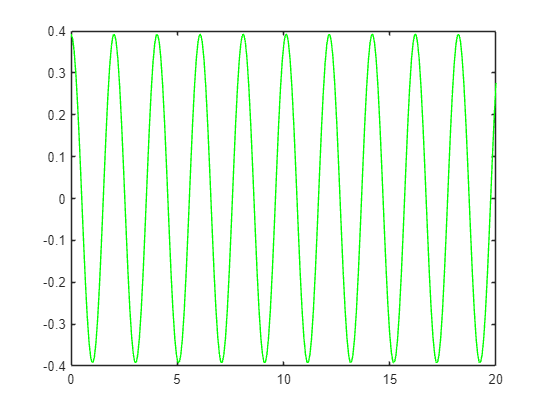

% numerica
g = 9.81; l = 1;
f = @(t, y) [y(2); -(g/l)*sin(y(1))];
y0 = [pi/8; 0];
tspan = [0 20];
h = 0.1;

[t, y] = odeRKF45(f, y0, tspan, h);
plot(t, y(1, :))

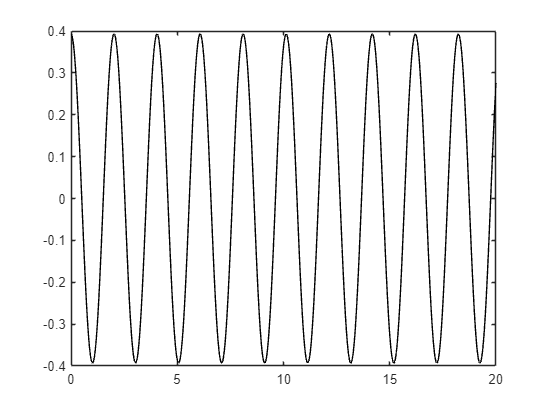

hold on
[t, y] = odeM23(f, y0, tspan, h);
plot(t, y(1, :))

hold off
title('RKF45 vs ODE23')
legend('RKF45', 'ODE23', 'location','best')
xlabel('$t$','interpreter','latex')
ylabel('$y$','interpreter','latex')

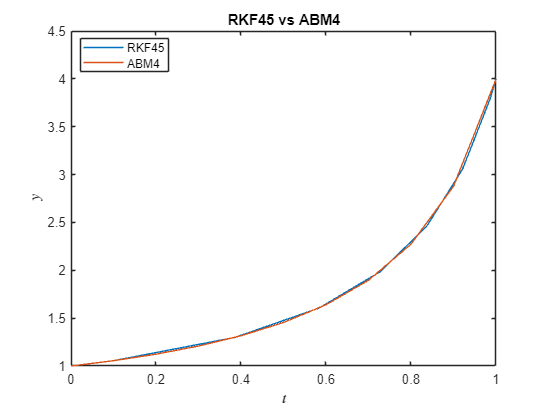

f = @(t, y) 1/2*(1+t).*y.^2;
y0 = 1;
tspan = [0 1];
h = 0.1;

[t, y] = odeRKF45(f, y0, tspan, h);
plot(t, y)
hold on
[t, y] = ABM4(f, y0, tspan, h);
plot(t, y)
hold off
title('RKF45 vs ABM4')
legend('RKF45', 'ABM4', 'location','best')
xlabel('$t$','interpreter','latex')
ylabel('$y$','interpreter','latex')